*Before running this code - prepare .wav files for import into MATLAB. Follow directions detailed in protocol (Preppingtable_forMATLABimport_10282024.docx).*

**Step 1: Import Raven Tables & Remove Bad Data**

MUST replace:

When new deployment: current directory location (line 1), and SNR threshold (lines 379/383/386), 338 (noise file)

When new file: filename in line 2, line 13, line 125/126, line 390/392, line 405 (with file #) before starting 

cd('E:\#DISSERTATION_final\CHAP 4 - PcTAG\Analysis\pc241001_J1_CATS\4_Raven_selections')
table_filename = '20241001-142340-CATS J1_02.Focal.selections_classification_QC.txt'; % Will give header warning - MATLAB modifying them to make them valid identifiers before crating variable names for the table.

opts = detectImportOptions(table_filename);
opts.VariableNames;
%opts = setvartype(opts,"x_OfClicks___R_NA_","string");
opts = setvartype(opts,"Clicks__R_0_","string");
opts = setvartype(opts,"ClickAssociation","string");
opts = setvartype(opts,"CallType_Final","string");
opts = setvartype(opts,"Overlap","string");

table_1 = readtable(table_filename, opts); 

**.wav Text file > .wav file name table**

Import .txt file with .wav file clip names

wavfilelist_filename = 'sel.241001.142340.txt';
table_wavfilelist = readtable(wavfilelist_filename,ReadVariableNames = false);

% Checks if 30th character in string of each row of the table is C or S - If C exclude
% to new table
T = string(table_wavfilelist.Var1);

% Initialize new arrays
newArray = {};   % To store rows with 'S' after the 6th period
newArray2 = {};  % To store rows with 'C' after the 6th period

% Loop through each row in cell array T
for i = 1:length(T)
    str = T{i}; % Get the string from the current row
    
    % Find all positions of periods in the string
    periodPositions = strfind(str, '.');
    
    % Check if there are at least 6 periods
    if length(periodPositions) >= 6
        % Get the position right after the 6th period
        positionAfter6thPeriod = periodPositions(6) + 1;
        
        % Check if this position is within the string's length
        if positionAfter6thPeriod <= length(str)
            % Check if the character at this position is 'S' or 'C'
            if str(positionAfter6thPeriod) == 'S'
                newArray{end + 1} = str;  % Add to newArray
            elseif str(positionAfter6thPeriod) == 'C'
                newArray2{end + 1} = str; % Add to newArray2
            end
        end
    end
end

% Initialize cell array for concatenation
connect_wavfiles = {};

% Loop through each string in newArray
for i = 1:length(newArray)
    % Split the string at periods
    split_str = strsplit(newArray{i}, '.');
    
    % Extract the 8th and 9th number values
    num_val_8 = split_str{8};
    num_val_9 = split_str{9};
    
    % Convert to string for matching
    compare_str = strcat(num_val_8, '.', num_val_9);
    
    % Loop through each string in newArray2 to find matching values
    for j = 1:length(newArray2)
        % Split the string in newArray2 at periods
        split_str2 = strsplit(newArray2{j}, '.');
        
        % Extract the 7th and 8th number values in newArray2
        num_val_8_2 = split_str2{8};
        num_val_9_2 = split_str2{9};
        
        % Convert to string for matching
        compare_str2 = strcat(num_val_8_2, '.', num_val_9_2);
        
        % Check if the values match
        if strcmp(compare_str, compare_str2)
            % Concatenate the matching strings in a new row
            connect_wavfiles = [connect_wavfiles; {newArray{i}, newArray2{j}}];
        end
    end
end

% Convert the cell array to a table
connect_wavfiles_table = cell2table(connect_wavfiles, 'VariableNames', {'S_filename', 'C_filename'});

Include only call information

% Use ismember to check for rows containing "C" in the 'Type' column
rowsWithC = ismember(table_1.SelectionType_S_N_C_, 'C');

% Create a new table containing only rows with "C" in the 'Type' column
table_callsonly = table_1(rowsWithC, :);

% Use ismember to check for rows containing "S" in the 'Type' column
rowsWithS = ismember(table_1.SelectionType_S_N_C_, 'S');

% Create a new table containing only rows with "S" in the 'Type' column
table_signalonly = table_1(rowsWithS, :);

**Connect .wav file names with table selections for calls only**

Confirm that the number of rows in table_callsonly and callonly_wavfile_list_T  match. If they do match combine them together.

if height(table_signalonly) == height(connect_wavfiles_table)
    all_calls_final = [connect_wavfiles_table  table_signalonly]; % Concatenates table Y to the end of table X
    disp('Table concatenated successfully!'); % Displays success message
else
    error('The tables have different heights and cannot be concatenated.');
end

Table concatenated successfully!


**Prune out "bad" data **

Including:

- Prune out any NF calls (Phase 1)

- Loud Background (Phase 2)

- Overlapping calls (Phase 3)

- Audio cut out periods (Phase 4)

% Remove all rows with NF
prune_phase1 = all_calls_final(ismember(all_calls_final.Animal_F_NF_, {'F', 'U'}), :);
prune_phase1_num = height(all_calls_final) - height(prune_phase1);

% Remove all rows with too loud of background noise
prune_phase2 = prune_phase1(~strcmp(prune_phase1.LoudBackground, 'Y'), :);
prune_phase2_num = height(prune_phase1) - height(prune_phase2);


% Removes overlap
prune_phase3 = prune_phase2(~contains(prune_phase2.Overlap, 'R'), :);
prune_phase3_1 = prune_phase3(~contains(prune_phase3.Overlap, '2'), :);
prune_phase3_2 = prune_phase3_1(~contains(prune_phase3_1.Overlap, '3'), :);
prune_phase3_3 = prune_phase3_2(~contains(prune_phase3_2.Overlap, '4'), :);
prune_phase3_4 = prune_phase3_3(~strcmp(prune_phase3_3.Overlap, '1'), :);
prune_phase3_5 = prune_phase3_4(~strcmp(prune_phase3_4.Overlap, '1C'), :);
prune_phase3_6 = prune_phase3_5(~strcmp(prune_phase3_5.Overlap, '1B'), :);
prune_phase3_num = height(prune_phase2) - height(prune_phase3_6);

% Removes rows with significant audio cut-out 
prune_phase4 = prune_phase3_6(~contains(prune_phase3_6.AudioCut_Out, 'Y'), :);
prune_phase4_num = height(prune_phase3_6) - height(prune_phase4);
all_good_calls = prune_phase4;

Compile pruning phase table

values_pruned = [prune_phase1_num ; prune_phase2_num ; prune_phase3_num; prune_phase4_num];
labels_pruned = {'NF'; 'Loud_Background'; 'Overlap'; 'Audio_Cutout'};

% Create the table
removed_data_stats_02 = table(labels_pruned,values_pruned);
save('Removed_data_stats_02.mat', 'removed_data_stats_02');

Prune out columns we don't need and renumber call order as "deployment_callnum" in seperate column

% 38 columns originally - remove unneeded columns
%removes 15 uneeded columns
all_good_calls.View=[];
all_good_calls.Channel=[];
all_good_calls.LowFreq_Hz_=[];
all_good_calls.DeltaFreq_Hz_=[];
all_good_calls.HighFreq_Hz_=[];
all_good_calls.PeakFreq_Hz_=[];
all_good_calls.CenterFreq_Hz_=[];
all_good_calls.BW90__Hz_=[];
all_good_calls.Dur90__s_=[];
all_good_calls.DeltaTime_s_=[];
all_good_calls.InbandPower_dBFS_=[];
all_good_calls.SNRNISTQuick_dB_=[];

%23 columns after removal - but then adds new call number in the last
%column 
all_good_calls.deployment_callnum = (1:height(all_good_calls))';

Confirm 22 columns and if so, name the final table when done removeing unusable data

if width(all_good_calls) == 22
    disp('Success: The table has 22 columns. Proceed!');
    %Add final table is "table_callsonly_final"
    table_callsonly_final = all_good_calls;

else
    disp('Alert: The table does not have 22 columns.');
end

Success: The table has 22 columns. Proceed!


**Step 2: Put all signal/call files into seperate folders**

***Signal only***

% Define the folder path where your .wav files are located
inputFolder = uigetdir;  % Update with your folder path
outputFolder = fullfile(inputFolder, 'signals');

% Create the new folder if it doesn't exist
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Get a list of all .wav files in the folder
fileList = dir(fullfile(inputFolder, '*.wav'));

% Loop through each file in the folder
for i = 1:length(fileList)
    % Get the filename
    fileName = fileList(i).name;
    
    % Find the positions of periods ('.') in the filename
    periodPositions = strfind(fileName, '.');
    
    % Check if there are at least 6 periods and if the letter after the 6th period is 'S'
    if length(periodPositions) >= 6 && periodPositions(6) + 1 <= length(fileName) ...
            && fileName(periodPositions(6) + 1) == 'S'
        
        % Move the file to the 'signals' folder
        movefile(fullfile(inputFolder, fileName), fullfile(outputFolder, fileName));
    end
end

disp('Files have been moved to the "signals" folder.');

Files have been moved to the "signals" folder.


***Clip only***

% Define the folder path where your .wav files are located
inputFolder = uigetdir;  % Update with your folder path
outputFolder = fullfile(inputFolder, 'clips');

% Create the new folder if it doesn't exist
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Get a list of all .wav files in the folder
fileList = dir(fullfile(inputFolder, '*.wav'));

% Loop through each file in the folder
for i = 1:length(fileList)
    % Get the filename
    fileName = fileList(i).name;
    
    % Find the positions of periods ('.') in the filename
    periodPositions = strfind(fileName, '.');
    
    % Check if there are at least 6 periods and if the letter after the 6th period is 'S'
    if length(periodPositions) >= 6 && periodPositions(6) + 1 <= length(fileName) ...
            && fileName(periodPositions(6) + 1) == 'C'
        
        % Move the file to the 'signals' folder
        movefile(fullfile(inputFolder, fileName), fullfile(outputFolder, fileName));
    end
end

disp('Files have been moved to the "clips" folder.');

Files have been moved to the "clips" folder.


**Extract only good calls**

Pull out all .wav files that are in the final table (all_good_calls) and put in seperate folders - remove all the bad wav files from the 

*Signals only*

% Prompt user to select folder containing .wav files
input_folder = uigetdir([], 'Select Folder Containing WAV Files');

% Define the new folder for good calls
output_folder = fullfile(input_folder, 'good_calls_S');

% Check if the output folder exists, if not, create it
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

% Get all .wav files in the input folder
wav_files = dir(fullfile(input_folder, '*.wav'));

% Loop through each wav file
for i = 1:length(wav_files)
    % Extract the filename (without extension) from the .wav file
    filename_with_extension = wav_files(i).name;
    
% Check if this filename (with .wav) is listed in the 'S_filename' column of the table
    if any(strcmp(all_good_calls.S_filename, filename_with_extension))
        % Full path of the current .wav file
        src_file = fullfile(input_folder, wav_files(i).name);
        
        % Destination path in the 'good_calls_S' folder
        dest_file = fullfile(output_folder, wav_files(i).name);
        
        % Copy the file to the new folder
        copyfile(src_file, dest_file);
        
        % Optionally, you can move the file instead of copying it
        % movefile(src_file, dest_file); % Uncomment if you want to move instead of copy
    end
end

disp('Selected .wav files have been copied to the good_calls_S folder.');

Selected .wav files have been copied to the good_calls_S folder.


*Clips only*

% Prompt user to select folder containing .wav files
input_folder = uigetdir([], 'Select Folder Containing WAV Files');

% Define the new folder for good calls
output_folder = fullfile(input_folder, 'good_calls_C');

% Check if the output folder exists, if not, create it
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

% Get all .wav files in the input folder
wav_files = dir(fullfile(input_folder, '*.wav'));

% Loop through each wav file
for i = 1:length(wav_files)
    % Extract the filename (without extension) from the .wav file
    filename_with_extension = wav_files(i).name;
    
% Check if this filename (with .wav) is listed in the 'S_filename' column of the table
    if any(strcmp(all_good_calls.C_filename, filename_with_extension))
        % Full path of the current .wav file
        src_file = fullfile(input_folder, wav_files(i).name);
        
        % Destination path in the 'good_calls_C' folder
        dest_file = fullfile(output_folder, wav_files(i).name);
        
        % Copy the file to the new folder
        copyfile(src_file, dest_file);
        
        % Optionally, you can move the file instead of copying it
        % movefile(src_file, dest_file); % Uncomment if you want to move instead of copy
    end
end

disp('Selected .wav files have been copied to the good_calls_C folder.');

Selected .wav files have been copied to the good_calls_C folder.


**STEP 3: Extract SNR **

Locate folders-

Before running thos code - create folder in "good_calls_S" that is called "spectrograms"

wavfileDir=uigetdir('','Select folder with good signals (s) only');
spectrogramDir= uigetdir('','Select save location folder for spectrograms');

myfiles=dir(fullfile(wavfileDir,'*.wav')); %gets all wav files in structure

Calculate SNR

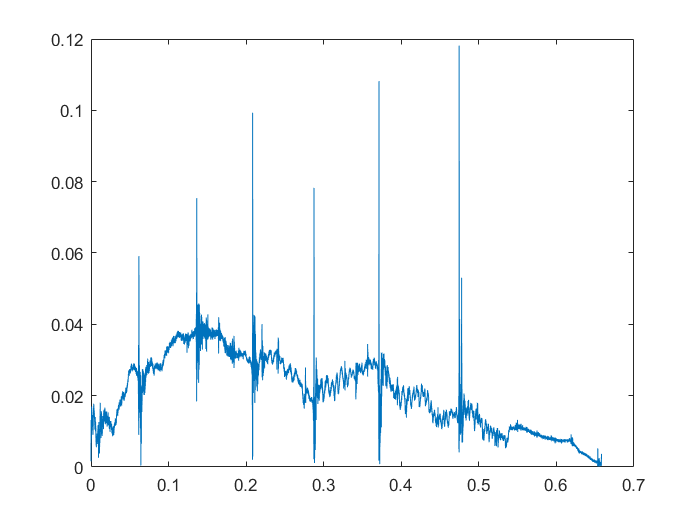

SNR_values = {}; % Initialize an array to store results (preallocate for efficiency)
SNR_files = {};

for k= 1:length(myfiles);
    basefile=myfiles(k).name;
    output= fullfile(wavfileDir, basefile);
    [filename, fs]= audioread(output);  
    % define a time scale
    t=(1:length(filename))/fs; 
    
    %time = (0:length(filename)-1)/fs; %plots time on the x-axis
    f_highpass = 500; %500
    order = 4;
    [b2, a2] = butter(order,f_highpass/(fs/2),'high'); 
    yf = filtfilt(b2,a2,filename) ; % filtfilt= filters twice in both directions to prevent distortion
    x_filt = abs(hilbert(yf));% Plots the envelope (removes the negative part of the axis)
    t_x_filt=(1:length(x_filt))/fs; 
    
    % Basic energy threshold detector
    env=envelope(yf); % using the discrete Fourier transform as implemented in hilbirt
    plot(t_x_filt,env);%plot (time,upper, time, lower, 'linewidth',1.0);
    threshold=(max(env))*0.01; % 0.01 - relative theshold so different for each individual wav file depending on sound. Exampe: If *0.5, it is taking 50% of the threshold
    [calldetectrow,cols,vals]=find(env>threshold);
    onlycall=(env(calldetectrow));
    t_onlycall=(1:length(onlycall))/fs; 
    
    base= string(basefile); % converts the output variable to a string
    newStr = erase(base,'.wav'); % removes the .wav portion of the string
    foldername=char(newStr); % converts the modified, shortened string back to a character
    callname= sprintf('callonly'); 
    jpegToSaveFileName = [foldername '_' callname]; % use path if you want to save to same directory
    
    outputFileName = fullfile(spectrogramDir, [jpegToSaveFileName, '_spectrogram.jpeg']);
    
    fft_size = 1024;
    windowsize = 512;
    window = hann(512);
    overlap = 0.50;

    % plot only call
    hFig = figure('Visible', 'off'); 
    spectrogram(onlycall,window,floor(overlap*windowsize),fft_size,fs,'yaxis');
    colorbar off
    title('Spectrogram');
    saveas(hFig, outputFileName);
    close(hFig);
        
%     % Make wav files of each call
%     wavfilename = sprintf([foldername '_callonly.wav'], onlycall);
%     audiowrite(wavfilename,onlycall,fs); %saves filtered version...need it to save original (filename) version
    
    %%%% CALCULATE SNR %%%%
    filename_noise = 'noise_241001.144730.53-CATS J1_02.wav';
    [x_noise,fs_noise] = audioread(filename_noise);
    t_noise_filt=(1:length(x_noise))/fs; 
    
    noise_filt_high = filtfilt(b2,a2,x_noise) ; % filtfilt= filters twice in both directions to prevent distortion
    noise_filt = abs(hilbert(noise_filt_high));% Plots the envelope (removes the negative part of the axis)
    t_noise_filt=(1:length(noise_filt))/fs; 
    SNR_values{k} = 10*log10(var(onlycall)/var(noise_filt));
    clear onlycall S F T wavfilename foldername  %will clear these variables specified each time so a new file can be run
    SNR_files{k} = basefile;
end

  
% Transpose
SNR_values_t = SNR_values';
SNR_files_t = SNR_files';

%convert to table
SNR_values_table = table(SNR_values_t);
SNR_files_table = table(SNR_files_t);

Column1 = table(SNR_values_table, 'VariableNames', {'SNR_value'});
Column2 = table(SNR_files_table, 'VariableNames', {'SNR_filename'});

C1 = table2array(Column1);
C2 = table2array(Column2);

SNR_stats = [C1, C2];

%%% Match SNR_stats with table_wavefiles_S
% Perform the join based on matching rows in SNR_stats and table_wavefiles_S
all_good_calls_SNR = innerjoin(SNR_stats, all_good_calls, 'LeftKeys', 'SNR_files_t', 'RightKeys', 'S_filename');

% Check if the result is empty
if isempty(all_good_calls_SNR)
    disp('No matches found');
else
    disp(all_good_calls_SNR);  % Display the concatenated table
end

    SNR_values_t                     SNR_files_t                                        C_filename                      Selection                BeginFile                        BeginDateTime            BeginTime_s_     EndClockTime      EndTime_s_    SelectionType_S_N_C_    Call_    Animal_F_NF_    Clicks__R_0_    ClickAssociation    SecondarySidebands_P_A_             Notes               Overlap     AudioCut_Out    LoudBackground      Chaos        Sequence     CallType_Final    deployment_callnum
    ____________    ______________________________________________    <

Implement threshold - everything >29 is considered the focal animal signal

% Convert the SNR_values_t column from cell to numeric if necessary
SNR_values_numeric = cell2mat(all_good_calls_SNR.SNR_values_t);

% Filter out rows where the SNR_values_t column is less than 29
all_good_calls_SNR_above29 = all_good_calls_SNR(SNR_values_numeric >= 29, :);


Add new column to the end with just larger category call type

% Extract the first character (number or letter) of each entry in 'CallType_Final'
% IF GIVES ERROR, THAT MEANS THERE IS A CLASSIFICATION MISSING 
first_char = cellfun(@(x) x(1), all_good_calls_SNR_above29.CallType_Final, 'UniformOutput', false);

% Add the new column to the table - goes from 25 to 26 columns
all_good_calls_SNR_above29.Call_Type_Category = first_char;

Rename variable

all_good_calls_SNR_above29_02 = all_good_calls_SNR_above29; 
% Save the new table to a .mat file 
save('SNR_above29_02.mat', 'all_good_calls_SNR_above29_02');

Add row at end of removed data summay to calculate number removed by SNR threshold

SNR_removed_num = height(all_good_calls) - height(all_good_calls_SNR_above29);

% Row to be added
newRowName = {'SNR_removed'};
newRowValue = SNR_removed_num; % Assuming both variables should have value 3

% Create a new row as a table
newRow = table(newRowName, newRowValue);
% Rename the columns
newRow.Properties.VariableNames = {'labels_pruned', 'values_pruned'};

% Add the new row to the existing table
removed_data_stats_02 = [removed_data_stats_02; newRow];